## Problem CM3 - 6/4/01

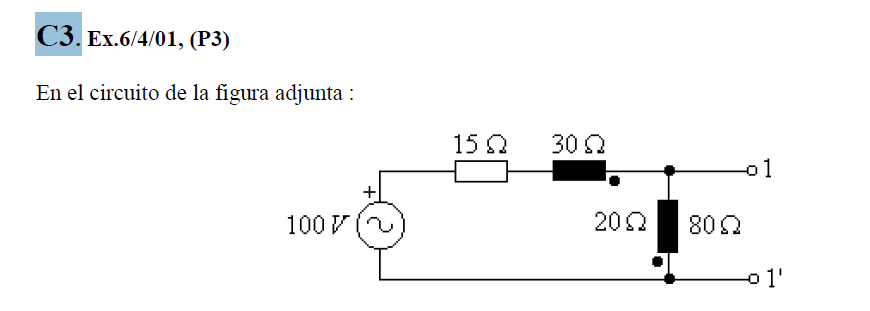

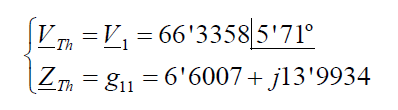

clear all
close all
clc
format short

Matrix (A) and independent vector (B) definition Ax=B

A=[1/15,-1/15,0,0,0,1;
  -1/15, 1/15,0,-1,0,0;
0,0,0,1,-1,0;
0,-1,1,-1i*30,-1i*20,0;
0,0,-1,-20*1i,-80*1i,0;
1,0,0,0,0,0]

A =    0.0667 + 0.0000i  -0.0667 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
  -0.0667 + 0.0000i   0.0667 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 -30.0000i   0.0000 -20.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 -20.0000i   0.0000 -80.0000i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



B=[0;0;0;0;0;100]

B =      0
     0
     0
     0
     0
   100



sol=inv(A)*B

sol = 	1.0e+02 *

   1.0000 + 0.0000i
   0.9901 + 0.0990i
   0.6601 + 0.0660i
  -0.0007 + 0.0066i
  -0.0007 + 0.0066i
  -0.0007 + 0.0066i



v1=sol(1)

v1 = 100

v2=sol(2)

v2 = 99.0099 + 9.9010i

v3=sol(3)

v3 = 66.0066 + 6.6007i

ix1=sol(4)

ix1 = -0.0660 + 0.6601i

ix2=sol(5)

ix2 = -0.0660 + 0.6601i

Thevenin calculation

uth=sol(3)

uth = 66.0066 + 6.6007i

uthm=abs(uth)

uthm = 66.3358

utha=angle(uth)*180/pi

utha = 5.7106

z=inv(A);
zth=z(3,3)

zth = 6.6007 + 13.9934i

Second option (eq. Norton)

clear all
close all
clc


Matrix (A) and independent vector (B) definition Ax=B

A=[1/15,0,-1,0;
    0,0,1,-1;
    -1,1,-1i*30,-1i*20;
    0,-1,-1i*20,-1i*80]

A =    0.0667 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i
  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 -30.0000i   0.0000 -20.0000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 -20.0000i   0.0000 -80.0000i



B=[100/15;0;0;0]

B =     6.6667
         0
         0
         0



sol=inv(A)*B

sol =   99.0099 + 9.9010i
  66.0066 + 6.6007i
  -0.0660 + 0.6601i
  -0.0660 + 0.6601i



v2=sol(1)

v2 = 99.0099 + 9.9010i

v3=sol(2)

v3 = 66.0066 + 6.6007i

ix1=sol(3)

ix1 = -0.0660 + 0.6601i

ix2=sol(4)

ix2 = -0.0660 + 0.6601i

Thevenin calculation


uth=sol(2)

uth = 66.0066 + 6.6007i

uthm=abs(uth)

uthm = 66.3358

utha=angle(uth)*180/pi

utha = 5.7106

z=inv(A);
zth=z(2,2)

zth = 6.6007 + 13.9934i